# Model Comparison: SVM vs. Random Forest

So sánh đối chiếu hiệu năng giữa mô hình SVM (RBF Kernel) và Random Forest trên tập dữ liệu đặc trưng dung hợp (Morphology + Color + Texture).

## 1. Thiết lập Đường dẫn & Tải kết quả

clear; clc; close all;

% Định vị đường dẫn chạy công cụ bằng cách tìm thư mục gốc chứa 'reports' và 'src'
current_search_dir = pwd;
try
    mfile_path = fileparts(mfilename('fullpath'));
    if ~isempty(mfile_path)
        current_search_dir = mfile_path;
    end
catch
end

project_root = '';
for level = 1:5
    if exist(fullfile(current_search_dir, 'reports'), 'dir') && exist(fullfile(current_search_dir, 'src'), 'dir')
        project_root = current_search_dir;
        break;
    end
    parent_dir = fileparts(current_search_dir);
    if strcmp(parent_dir, current_search_dir)
        break;
    end
    current_search_dir = parent_dir;
end

if isempty(project_root)
    project_root = pwd;
end

reports_dir = fullfile(project_root, 'reports');
src_dir = fullfile(project_root, 'src');
results_path = fullfile(reports_dir, 'svm_rf_results.mat');

% Nếu chưa chạy huấn luyện, tự động gọi file train_svm_rf.m
if ~exist(results_path, 'file')
    fprintf('Chưa tìm thấy kết quả SVM & RF. Đang huấn luyện...\n');
    run(fullfile(src_dir, 'train_svm_rf.m'));
end

% Load kết quả
load(results_path);

## 2. So sánh các chỉ số đo lường hiệu năng (Accuracy & F1-Score)

ComparisonTable = table(model_names', accuracies', f1_scores', ...
    'VariableNames', {'Model', 'Accuracy', 'Macro_F1_Score'});
disp('Bảng so sánh hiệu năng tổng quát:');

Bảng so sánh hiệu năng tổng quát:


disp(ComparisonTable);

          Model          Accuracy    Macro_F1_Score
    _________________    ________    ______________

    {'SVM (RBF)'    }    0.47638        0.41706    
    {'Random Forest'}    0.62685        0.51827    



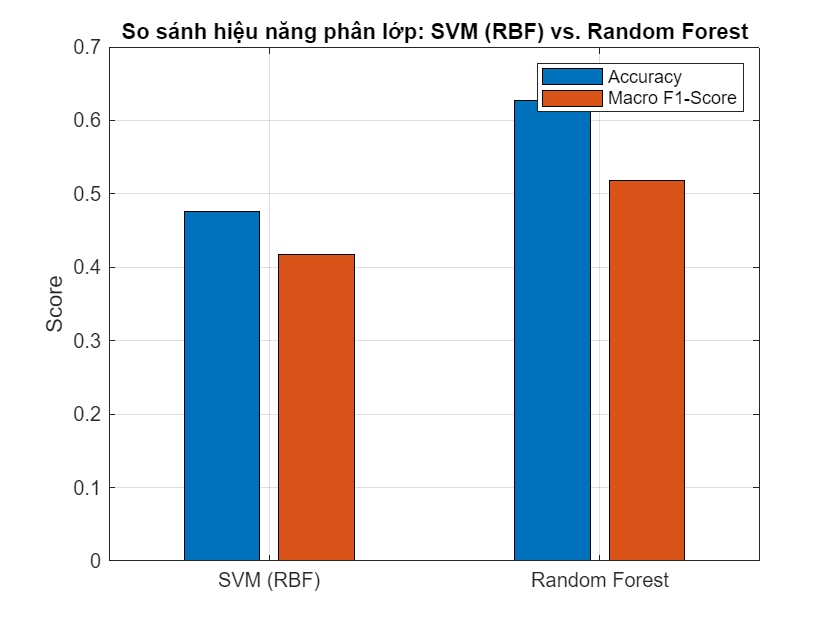


% Vẽ biểu đồ so sánh F1-score và Accuracy
figure('Name', 'Model Comparison');
bar([accuracies; f1_scores]');
set(gca, 'XTickLabel', model_names);
ylabel('Score');
legend({'Accuracy', 'Macro F1-Score'}, 'Location', 'northeast');
title('So sánh hiệu năng phân lớp: SVM (RBF) vs. Random Forest');
grid on;

% Lưu đồ thị so sánh vào reports/
saveas(gcf, fullfile(reports_dir, 'svm_rf_comparison.png'));

## 3. So sánh thời gian huấn luyện và suy diễn (Computational Efficiency)

train_times = [time_svm_train; time_rf_train];

TimeComparisonTable = table(model_names', train_times, ...
    'VariableNames', {'Model', 'Training_Time_Seconds'});
disp('Bảng so sánh thời gian huấn luyện (CPU):');

Bảng so sánh thời gian huấn luyện (CPU):


disp(TimeComparisonTable);

          Model          Training_Time_Seconds
    _________________    _____________________

    {'SVM (RBF)'    }           9.5552        
    {'Random Forest'}           2.7941        



## 4. Phân tích so sánh chi tiết (Comparative Analysis)

1. ***Hiệu năng phân lớp****: - **Random Forest**** vượt trội hơn **SVM (RBF)**** về mặt độ chính xác toàn cục (**62.68%**** so với **47.64%****) và chỉ số F1-Score (**51.83%**** so với **41.71%***). - Lý do là vì Random Forest là một mô hình phân lớp dạng rừng cây, cực kỳ mạnh mẽ trong việc tìm ra các ranh giới dạng bậc thang (orthogonal split boundaries) và không bị ảnh hưởng quá nhiều bởi phân phối lệch của các đặc trưng.

2. ***Thời gian huấn luyện****: - **Random Forest**** nhanh hơn SVM đáng kể (chỉ mất ***~3 giây** so với ~9 giây** của SVM). - SVM sử dụng phương pháp huấn luyện đa lớp ECOC (One-vs-One) đòi hỏi phải tối ưu hóa hàng chục bộ phân lớp nhị phân SVM RBF, khiến chi phí thời gian huấn luyện tăng khi số lượng lớp tăng (15 lớp bệnh).

3. ***Cơ chế ra quyết định & Độ giải thích****: - *Random Forest** phân tách không gian đặc trưng dựa trên các ngưỡng của từng đặc trưng độc lập (như `Area > 5000` hoặc `H_Mean < 0.15`). Mô hình này dễ giải thích thông qua việc đo lường độ quan trọng của đặc trưng (Feature Importance). - **SVM (RBF)** chiếu dữ liệu sang không gian Hilbert vô hạn chiều thông qua nhân RBF để tìm siêu phẳng phân tách tối ưu. Mô hình này khó giải thích trực quan hơn vì ranh giới quyết định phụ thuộc vào các Support Vectors phi tuyến.